## Read Task File

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mohammad\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


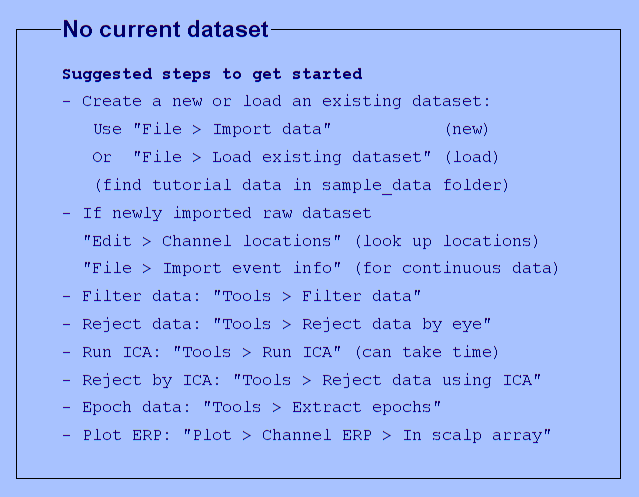

You are using the latest version of EEGLAB.


clear all
eeglab

T = readtable('task_track_file.csv','Format','%d%s%s%s%d%s%d%s%d%s%d')

T = 75×11 table
    Var1        local_file_path                 raw_data_file_name                         preprocessed_one                flag1                  ERP_mat_file                  flag2                      PAC_dist                       flag3                PAC_dist_mean_channel                flag4
    ____    _______________________    ____________________________________    ________________________________________    _____    ________________________________________    _____    _____________________________________________    _____    _____________________________________________    _____

      0     {

## Preprocess

Highpass_low = 1; % in Hz
Highpass_High = 150; % in Hz
Notch_low = 59.9; % in Hz
Notch_High = 60.1;% in Hz
Notch_order = 16500;

Path = 'G:\\filmuniversity\\Master sharif\\MasterProject\\data\\parkinsons-oddball';
channellocationfile = sprintf('%s\\%s\\%s',Path,T{i,2}{1},'sub-001_ses-01_task-Rest_electrodes.tsv');

for i=1:75
    load_path = sprintf('%s\\%s',Path,T{i,2}{1});
    EEG = pop_loadset(T{i,3}{1},load_path);
    EEG = pop_chanedit(EEG,'load',{channellocationfile ,'filetype','autodetect'});
    EEG = pop_select( EEG, 'nochannel',{'X','Y','Z','VEOG'});
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Notch_low,'hicutoff',Notch_High,'filtorder',Notch_order,'revfilt',1);
    EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',12,'Highpass','off','BurstCriterion','off','WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_interp(EEG1, EEG.chanlocs, 'spherical');
    EEG = pop_reref( EEG, []);
    EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',15,'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_reref( EEG, []);
    EEG = pop_saveset( EEG, 'filename',T{i,4}{1},'filepath',load_path);
    T{i,5}(1) = 1;
    writetable(T,'task_track_file.csv')
end